# Cours 07.12.22

clear;clc;close;
% Interpolation spline
% comparaison entre interpolation polynomiale et interpolation spline
% pour la fonction f(x9 = 1/(1+25*x^2) et 10 points
% équidistants entre -1 et 1

x = linspace(-1, 1, 10);
f = 1./(1 + 25*x.^2);

c = polyfit(x, f, 9);

xx = linspace(-1, 1, 1e3);
p = polyval(c, xx);

% Jusqu'ici polynome de degre 9


## Spline

x;
f;
xx;
s = spline(x, f, xx);

plot(x, f, 'o', xx, p, 'r', xx, s, 'b', xx, 1./(1+25*xx.^2), 'g');
legend('Points', 'interpolation degre 9', 'spline', 'fonction reelle');



## Moindres carrés

clear;clc;close;
format default
format compact
disp("Moindres carrés : ");

Moindres carrés : 



% Valeures d'entrée en X
t = 1950:10:2020;
t = t(:)

t =         1950
        1960
        1970
        1980
        1990
        2000
        2010
        2020


% Valeurs d'entrée en Y
P = [150.697, 179.323, 203.212, 226.505, 249.633, 281.422, 309.163, 329.5]'

P =   150.6970
  179.3230
  203.2120
  226.5050
  249.6330
  281.4220
  309.1630
  329.5000



% Modèle linéaire
A = [t ones(size(t))]

A =         1950           1
        1960           1
        1970           1
        1980           1
        1990           1
        2000           1
        2010           1
        2020           1



% Equations normales : At*A*x = At*P
B = A'*A

B =     31526000       15880
       15880           8


b = A'*P

b = 1.0e+06 *

    3.8408
    0.0019


format short e
x = B\b

x =    2.5697e+00
  -4.8597e+03



tt = 1950:2030;
pop = polyval(x, tt);

% createfigure_07_12_22(t, P);

plot(t, P, 'o', tt, pop, 'r');

x_2030 = polyval(x, 2030)

x_2030 =    3.5682e+02



% Si on veut faire passer un polynôme de degré 2 alors A devient 
A = [t.^2 t ones(size(t))]

A =      3802500        1950           1
     3841600        1960           1
     3880900        1970           1
     3920400        1980           1
     3960100        1990           1
     4000000        2000           1
     4040100        2010           1
     4080400        2020           1


% Le reste de la résolution est la même 
B2 = A'*A;
b2 = A'*P;
x2 = B2\b2

x2 =    9.0911e-04
  -1.0394e+00
  -1.2781e+03



cond(B2)*eps

ans =    2.5502e+05

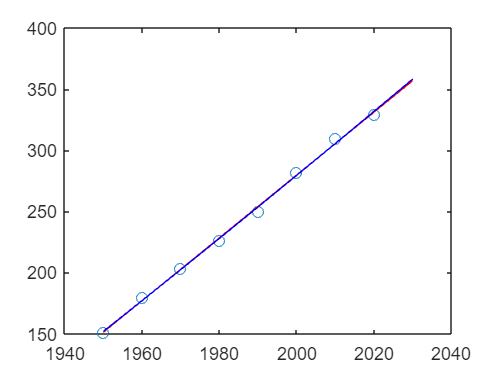

% Nombre de condition mauvais : 10^21
% ordre de grandeur dans B2 très différents (10^14 vs 10^0)
% On vera la prochaine fois comment corriger ce problème...

pop = polyval(x2, tt);
hold on;
plot(tt, pop, 'b');